## **Procesamiento adicional para análisis de datos**

Se toma a partir de la tabla en 'Tabla.mat', se reduce la tabla y se agregan indicadores de velocidad. Se muestran gráficas con algunos resultados preliminares

%% Una tabla más corta y legible, solo incluye variables númericas y categóricas relevante
load Tabla.mat
T = table(Tabla.Bus, categorical(Tabla.NombreRuta), ...
    Tabla.ID, Tabla.Sexo, categorical(Tabla.HorarioRuta), Tabla.HoraInicio, ...
    Tabla.HoraFin, Tabla.AcelePorcen1, Tabla.AcelePorcen2, ...
    Tabla.FrePorcen1, Tabla.FrePorcen2, ...
    milliseconds(cellfun(@mean,Tabla.DurPosMax)), ...
    milliseconds(cellfun(@mean,Tabla.DurNegMax)), ... 
    Tabla.KilometrosRuta, Tabla.Fre_km, Tabla.Acc_km, ...
    Tabla.PromRiesgo, Tabla.consumoPorKilometro,'VariableNames',...
    ["BusID", "Ruta", "CondID", "Sexo", "FranjaHora", "HoraIni", ...
    "HoraFin", "AceP1", "AceP2","FreP1", "FreP2", ...
    "DurAc", "DurFre", "kmRuta", "Fre_km", "Ace_km", ...
    "Riesgo", "Cons_km"]);

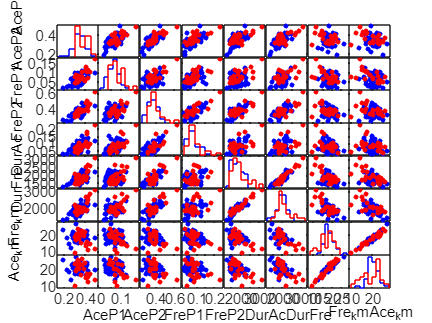

% Para analizar todos las combinaciones de dos variables
%% Graficamos todos los pares de variables numéricas, contra una categórica elegida (colores)
% T_num = T(:,[8:13 15 16]);
% T_num = T(:,[8:13]);
% varNames = T_num.Properties.VariableNames;
% % T_num = table2array(T(:,[8:13 15 16]));
% T_num = table2array(T(:,[8:13]));
% figure
% gplotmatrix(T_num,[],T.BusID,['c' 'b' 'm' 'g' 'r'],[],[],false);
% % text([.08 .24 .43 .66 .83], repmat(-.1,1,5), varNames, 'FontSize',8);
% % text(repmat(-.12,1,5), [.86 .62 .41 .25 .02], varNames, 'FontSize',8, 'Rotation',90);
% v =6;
% text(linspace(.08,.93,v), repmat(-.1,1,v), varNames, 'FontSize',8);
% text(repmat(-.12,1,v), linspace(.96,.02,v), varNames, 'FontSize',8, 'Rotation',90);

% Tb = T(T.BusID~='bus_4012',[8:13 15 16]);
% varNames = Tb.Properties.VariableNames;
% Tb = T(T.BusID~='bus_4012',[4 8:13 15 16]);
% Tb_num = table2array(T(T.BusID~='bus_4012',[8:13 15 16]));
% figure
% gplotmatrix(Tb_num,[],Tb.Sexo,['b' 'r' 'k'],[],[],false);
% % text([.08 .24 .43 .66 .83], repmat(-.1,1,5), varNames, 'FontSize',8);
% % text(repmat(-.12,1,5), [.86 .62 .41 .25 .02], varNames, 'FontSize',8, 'Rotation',90);
% v = 8;
% text(linspace(.08,.93,v), repmat(-.1,1,v), varNames, 'FontSize',8);
% text(repmat(-.12,1,v), linspace(.96,.02,v), varNames, 'FontSize',8, 'Rotation',90);


Tsex = T(T.Sexo~='NA',:);

Tb = Tsex(Tsex.BusID=='bus_4025',[8:13 15 16]);
varNames = Tb.Properties.VariableNames;
Tb = Tsex(Tsex.BusID=='bus_4025',[4 8:13 15 16]);
Tb_num = table2array(Tsex(Tsex.BusID=='bus_4025',[8:13 15 16]));
figure
gplotmatrix(Tb_num,[],Tb.Sexo,['b' 'r'],[],[],false);
% text([.08 .24 .43 .66 .83], repmat(-.1,1,5), varNames, 'FontSize',8);
% text(repmat(-.12,1,5), [.86 .62 .41 .25 .02], varNames, 'FontSize',8, 'Rotation',90);
v = 8;
text(linspace(.08,.93,v), repmat(-.1,1,v), varNames, 'FontSize',8);
text(repmat(-.12,1,v), linspace(.96,.02,v), varNames, 'FontSize',8, 'Rotation',90);


% Tc = Tsex(Tsex.BusID=='bus_4012',[8:13 15 16]);
% varNames = Tc.Properties.VariableNames;
% Tc = Tsex(Tsex.BusID=='bus_4012',[4 8:13 15 16]);
% Tc_num = table2array(Tsex(Tsex.BusID=='bus_4012',[8:13 15 16]));
% figure
% gplotmatrix(Tc_num,[],Tc.Sexo,['b' 'r'],[],[],false);
% % text([.08 .24 .43 .66 .83], repmat(-.1,1,5), varNames, 'FontSize',8);
% % text(repmat(-.12,1,5), [.86 .62 .41 .25 .02], varNames, 'FontSize',8, 'Rotation',90);
% v = 8;
% text(linspace(.08,.93,v), repmat(-.1,1,v), varNames, 'FontSize',8);
% text(repmat(-.12,1,v), linspace(.96,.02,v), varNames, 'FontSize',8, 'Rotation',90);


% T_num2 = T(:,14:23);
% varNames2 = T_num2.Properties.VariableNames;
% T_num2 = table2array(T(:,14:23));
% figure
% gplotmatrix(T_num,[],T.Sexo,['b','r','k'],[],[],false);
% text(linspace(.08,.83,10), repmat(-.1,1,10), varNames, 'FontSize',7);
% text(repmat(-.12,1,10), linspace(.86,.02,10), varNames, 'FontSize',7, 'Rotation',90);

## Indicadores de velocidad

% Para evitar promediar segmentos de velocidades muy diferentes y evitar
% hacer división de segmentos específicos ruta por ruta,
% se usan 9 segmentos arbitrarios dividiendo toda la ruta en 10 segmentos
% de distancias iguales, y analizando solo los primeros 9 (el último suele 
% ser irregular).

% load('Tabla.mat')

rutas = unique(Tabla.NombreRuta); % Conjunto de rutas únicas
t_ = struct();

% Para cada ruta 
figure
for ii = 1:length(rutas)
    t_.(rutas(ii)) = Tabla(Tabla.NombreRuta == rutas(ii),:);

% t_ = 
% 
%   struct with fields:
% 
%     A617: [71×34 table]
%     H617: [66×34 table]
%     A601: [18×34 table]
%     H601: [18×34 table]
%     L613: [45×34 table]
%     H613: [41×34 table]
%     A618: [6×34 table]
%     H618: [4×34 table]
%     K629: [10×34 table]
%     H629: [9×34 table]
%     K635: [3×34 table]
%     H635: [1×34 table]
%      T04: [1×34 table]
%     L636: [23×34 table]
%     H636: [21×34 table]
% end

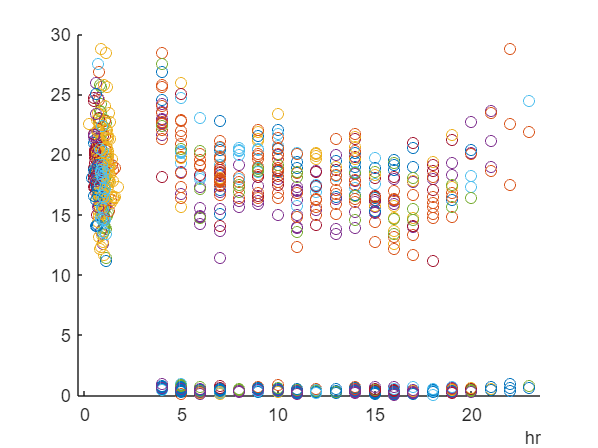

% for ii = 1:length(rutas)

% Cada ruta se divide en 10 segmentos iguales
    nSegments = 10;
    d_ = (1e3)*(1:9)*mean(t_.(rutas(ii)).KilometrosRuta)/nSegments;
    vel_ = nan*ones(size(t_.(rutas(ii)),1),nSegments-1);
    % La matriz vel_ guarda el promedio de las velocidades no-cero de cada
    % recorrido (i) en cada segmento (j) para cada ruta (ii), en km/h

    % Para cada recorrido (i) de cada ruta (ii)
    for i = 1:size(t_.(rutas(ii)),1)
        lim_ = nan*ones(nSegments-1,1); lim_(1) = 1;
        % Para cada segmento (j) de cada recorrido (i)
        for j = 1:nSegments-1
            % Posición (índice) límite del segmento
            lim_(j+1) = find(cumsum(t_.(rutas(ii)).Distancia{i}) < d_(j),1,'last');
            if lim_(j+1) < numel(t_.(rutas(ii)).Velocidad{i})
                vel_(i,j) = mean(nonzeros(3.6*t_.(rutas(ii)).Velocidad{i}(lim_(j):lim_(j+1))));
            else % si el final del límite del segmento es mayor que el número de muestras en el recorrido
                vel_(i,j) = nan;
            end
        end    
        % plot(cumsum(t_.A617.Distancia{i}(1:lim_(1))), 3.6*t_.(A617).Velocidad{i}(1:lim_(1)))
        % plot(cumsum(t_.A617.Distancia{i}(1:end-1)), 3.6*t_.A617.Velocidad{i})
    end
    
%% Indicador 1: Speed score
    % 1- Se normaliza por el rango del segmento (formado por todos los
    % recorridos de una ruta en ese segmento)
    % 2- Se promedia el valor normalizado, entre todos los 9 segmentos
    speed = mean(vel_,2,'omitmissing');
    speed_score = mean((vel_ - min(vel_))./range(vel_),2,'omitmissing');
    idx = find(T.Ruta == rutas(ii));
    T.Speed(idx) = speed;
    T.S_Score(idx) = speed_score;

    % Gráfica de speed score vs hora de inicio
    r = hours(round(hours(minutes(minute(t_.(rutas(ii)).HoraInicio))))); % minutes round
    scatter(hours(hour(t_.(rutas(ii)).HoraInicio))+r,speed_score,'DisplayName',rutas(ii))

    % Gráfica de speed vs hora de inicio
    scatter(hours(hour(t_.(rutas(ii)).HoraInicio))+r,speed,'DisplayName',rutas(ii))

    % Es claro que la velocidad neta y el speed_score, dependen de la hora
    % de inicio     
   
%%Indicador 2: Cum score    
    % 1- Se separan todos los recorridos por hora de inicio
    % 2- Se ordenan en orden ascendente: primero el de menor speed_score 
    % 3- Por cada hora de inicio: Se encuentra la diferencia de cada
    % recorrido vs el de menor speed_score
    % - El cum_score "castiga" (o aumenta) a un recorrido que tenga un
    % speed_score por encima del mínimo de su misma hora de inicio.
    % - Si solo hay un recorrido en esa hora de inicio, cum_score = nan;

    % Se crea un arreglo [hora de inicio, speed_score, 1:rutas], ordenado
    % por speed_score ascendente
    tmp = sortrows([hours(hours(hour(t_.(rutas(ii)).HoraInicio))+r)  speed_score (1:numel(t_.(rutas(ii)).HoraInicio))'],2);
    hrs = unique(tmp(:,1));
    % Se calcula por cada hora del día, el promedio del speed_score
    avg_speed_hr = accumarray(tmp(:,1),tmp(:,2),[],@mean);
    tmp(:,4) = nan*ones(size(tmp,1),1);
    for jj = 1:numel(hrs)        
        % El cum_score es el acumulado de la diff de speed_score de cada
        % hora del día, en la tabla ordenada.
        % Es decir, se aumenta con: mayor diff de speed_score y mayor
        % número de muestras en cada hora
        cum_score = cumsum([0; diff(tmp(tmp(:,1)==hrs(jj),2))]);
        tmp(tmp(:,1)==hrs(jj),4) = cum_score;
        tmp(tmp(:,1)==hrs(jj),5) = avg_speed_hr(hrs(jj));
    end
    tmp = sortrows(tmp,3); % organizar según orden inicial en la columna 3
    T.Cum_S_Score(idx) = tmp(:,4); % Cumulative speed score (compared to other scores in the same route, same start hour)
    % El cum_score, castiga estar lejos de mínimo en cada hora de inicio.
    % Pero cuando hay pocas muestras, puede ser muy sesgado.

%% Indicador 3: Desv Speed Score
    % Puede ser mejor revisar la desviación del speed_score de un
    % recorrido vs la media del speed_score para esa hora de inicio.
    % Eso es el Desv_s_score.
    T.Desv_S_Score(idx) = speed_score - tmp(:,5); % Desviación respecto la media de la hora inicial

    % scatter(hours(hour(t_.(rutas(ii)).HoraInicio))+r,speed_score,'DisplayName',rutas(ii))
    % plot(hours(unique(tmp(:,1))),nonzeros(accumarray(tmp(:,1),tmp(:,2),[],@mean)),'DisplayName',rutas(ii))

    %% Gráficas de análisis preliminares
    hold on
    % scatter(t_.(rutas(ii)).consumoPorKilometro,speed,'DisplayName',rutas(ii))
    % scatter(t_.(rutas(ii)).consumoPorKilometro,T.Ace_km(idx))
    % scatter(t_.(rutas(ii)).PromRiesgo,T.Cum_S_Score(idx))
    % scatter(t_.(rutas(ii)).consumoPorKilometro,T.Desv_S_Score(idx))
    % scatter(t_.(rutas(ii)).Promedio_riesgo_kalman,T.Desv_S_Score(idx))
    
end
T.Cum_S_Score(T.Cum_S_Score==0) = NaN;
T.Desv_S_Score(T.Desv_S_Score==0) = NaN;